%% Decrepet, funktionen er lagt ind under unstructed uncertainties i test.mlx


M=Mn

M =
 
  From input 1 to output...
                 9.34e-07 s^47 + 5.899e-05 s^46 + 0.001747 s^45 + 0.03221 s^44 + 0.4139 s^43 + 3.932 s^42 + 28.58 s^41 + 162.2 s^40 + 727.3 s^39 + 2588 s^38 + 7300 s^37 + 1.621e04 s^36 + 2.793e04 s^35 + 3.654e04 s^34 + 3.506e04 s^33 + 2.343e04 s^32 + 1.013e04 s^31 + 2622 s^30 + 438.2 s^29 + 50.79 s^28 + 4.295 s^27 + 0.2738 s^26 + 0.01343 s^25 + 0.0005128 s^24 + 1.53e-05 s^23 + 3.553e-07 s^22 + 6.346e-09 s^21 + 8.515e-11 s^20 + 8.219e-13 s^19 + 5.246e-15 s^18 + 1.789e-17 s^17 + 4.669e-21 s^16 - 1.241e-22 s^15 - 1.635e-28 s^14 - 9.902e-35 s^13 - 3.653e-41 s^12 - 9.171e-48 s^11 - 1.659e-54 s^10 - 2.23e-61 s^9 - 2.268e-68 s^8 - 1.757e-75 s^7 - 1.037e-82 s^6 - 4.621e-90 s^5 - 1.526e-97 s^4 - 3.614e-105 s^3 - 5.795e-113 s^2 - 5.626e-121 s - 2.493e-129
   1:  -----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

s = tf('s');
% M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
%       0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
%       0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
%       0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

% M = [1/(2*s+1), 1, (s-2)/(2*s+4);
%     -1, s/(s^2+s+1), 1/(s+1)^2 ;
%     (3*s)/(s+5), -1/(4*s+1), 1];

W = logspace(-1,3,100);
SV = sigma(M, W);
spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 100/100



[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:)

ans = ans(:,:,1) =

   1.0e+04 *

   0.4937 + 1.5113i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.4937 + 1.5113i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.4937 + 1.5113i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.4937 + 1.5113i


ans(:,:,2) =

   1.0e+04 *

   0.4961 + 1.6591i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.4961 + 1.6591i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.4961 + 1.6591i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.4961 + 1.6591i


ans(:,:,3) =

   1.0e+04 *

   0.4989 + 1.8213i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.4989 + 1.8213i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.4989 + 1.8213i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

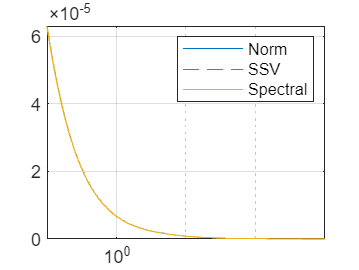

upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,'--',W,spectral)
% ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'../Images/SSV_PLOT_Procedure2','epsc')